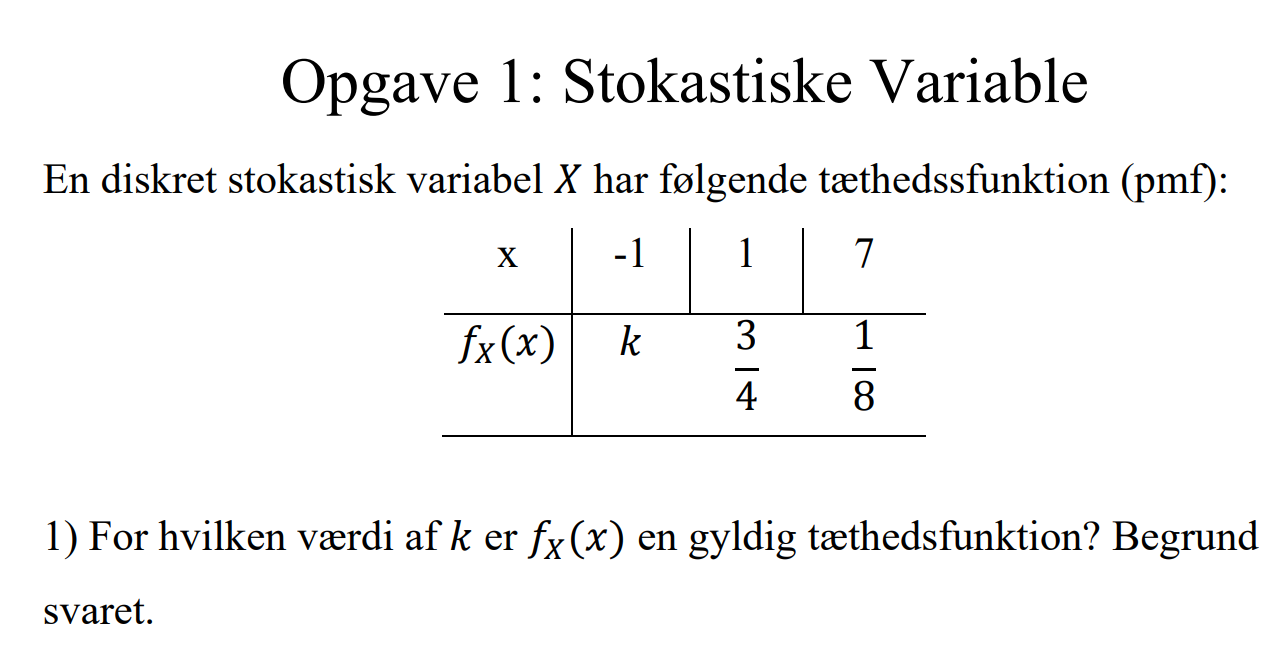

clearvars

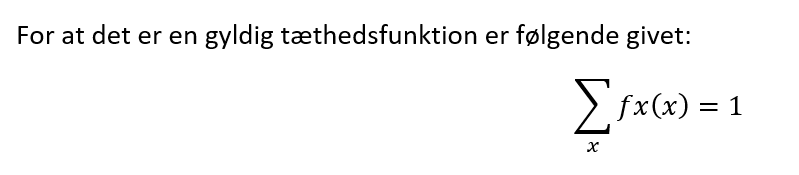

syms k 
x=[-1 1 7]

x =     -1     1     7


fx = [ k 3/4 1/8]

$$fx = \left(\begin{array}{ccc} k & \frac{3}{4} & \frac{1}{8} \end{array}\right)$$


k = solve(sum(fx)== 1 , k)

$$k = \frac{1}{8}$$

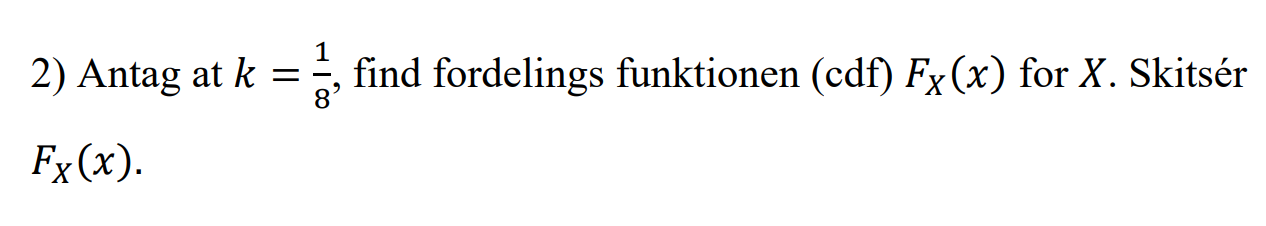

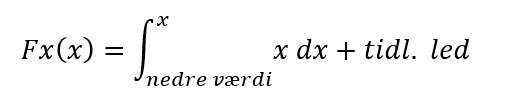

syms x
Fx(x) = piecewise( x < -1, 0, ...
   x           -1 <= x < 1, k, ...
              1 <= x < 7, k+3/4, ...
              7 <= x, k + 3/4 + 1/8)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<-1\\ \frac{1}{8} & \text{ if }x<1\\ \frac{7}{8} & \text{ if }x\in \left[1,7\right)\\ 1 & \text{ if }7\leq x \end{array}\right.$$

          
fplot(Fx, [-5, 10],'-r','LineWidth',2)

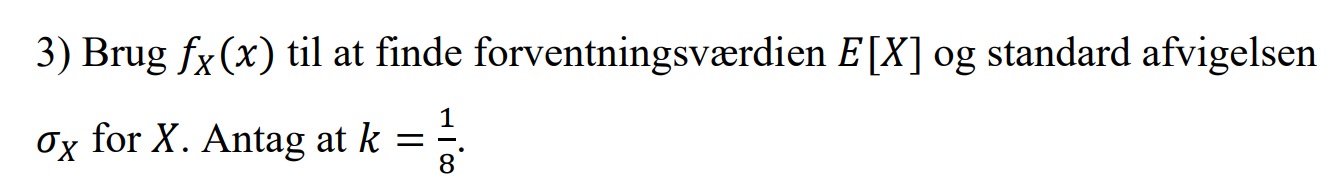

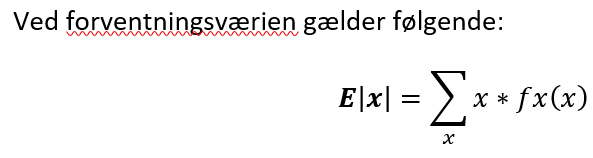

fx = [ 1/ 8 3/4 1/8]

fx =     0.1250    0.7500    0.1250


x=[-1 1 7]

x =     -1     1     7


Ex= sum(x.*fx)

Ex = 1.5000

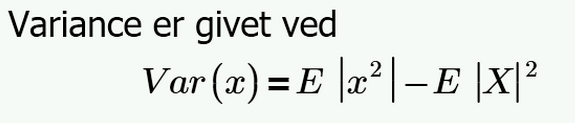

Ex2= sum(x.^2.*fx)

Ex2 = 7

var = Ex2 - Ex^2

var = 4.7500

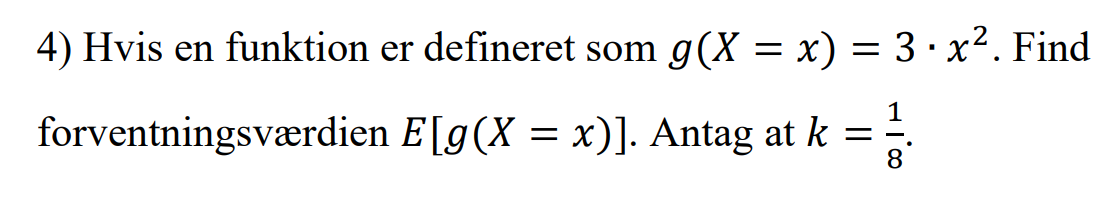

E_G_3_X2= 3*Ex2

E_G_3_X2 = 21

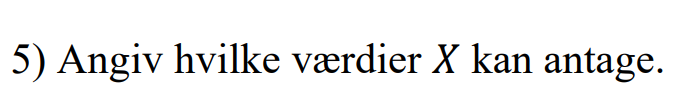

X kan antage -1, 1 og 7

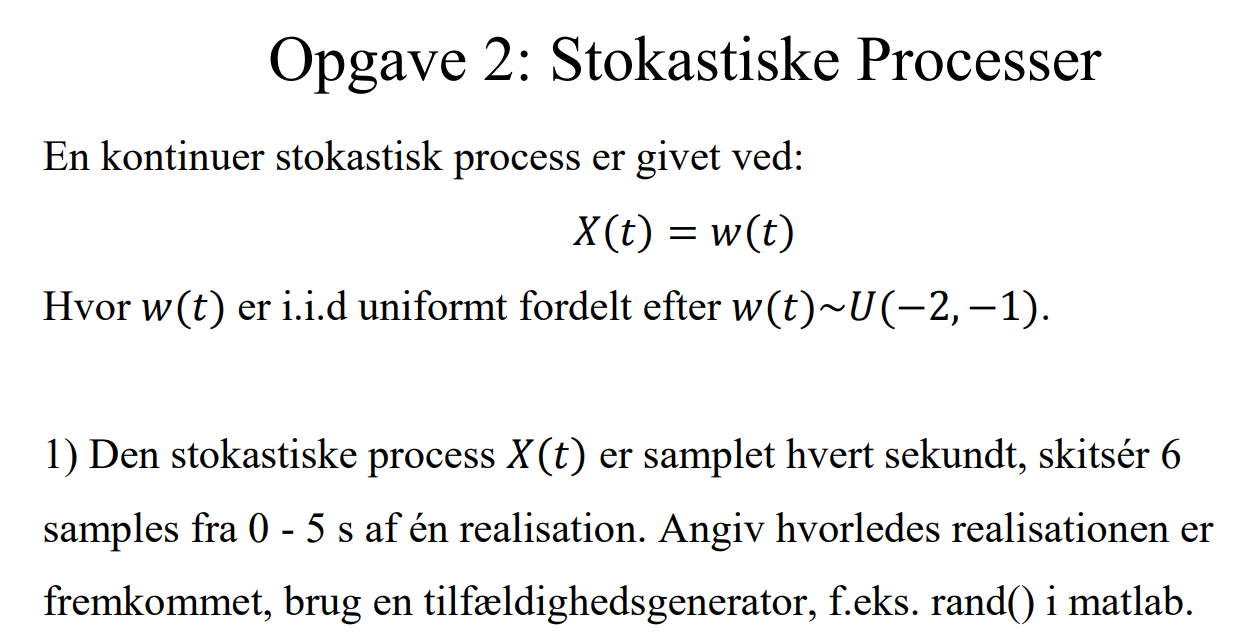

clearvars
close all
t = 0:1:5;
samples = length(t);
a = -2;
b = -1 

b = -1

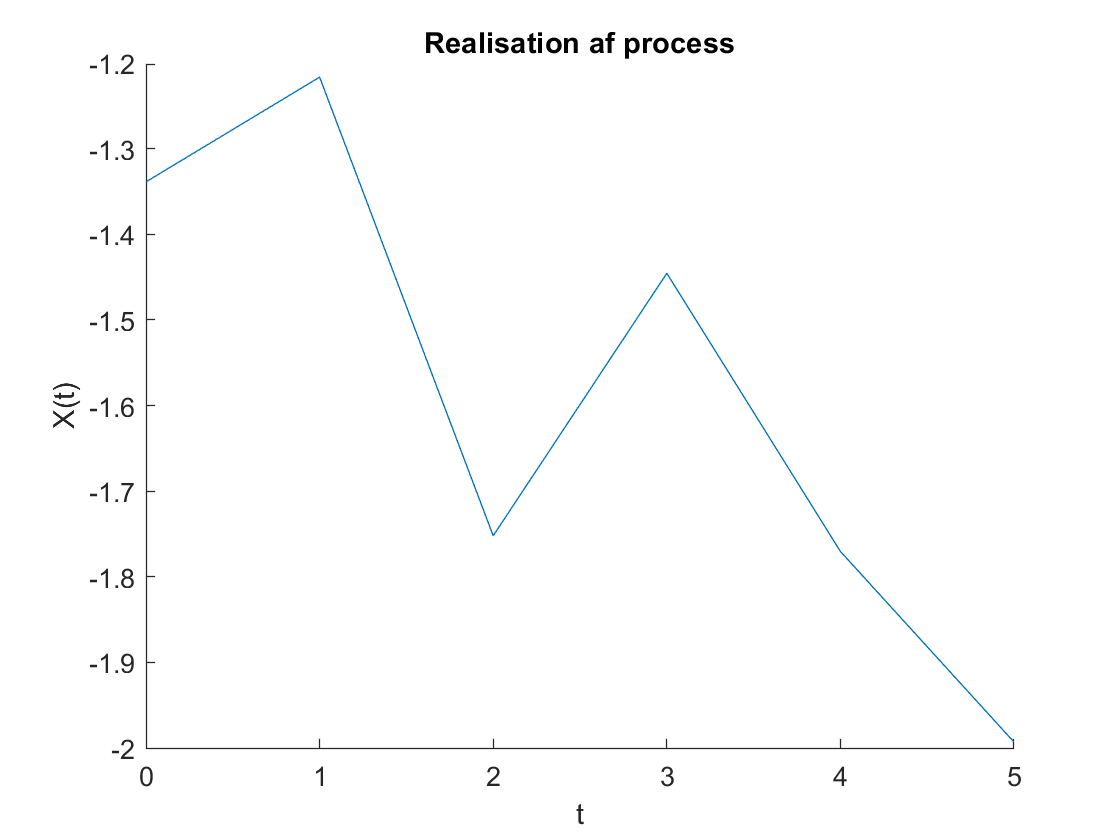

w = rand(1,samples)-2;
figure(1)
hold on
xlabel("t"); ylabel("X(t)"); title("Realisation af process");
plot(t, w)

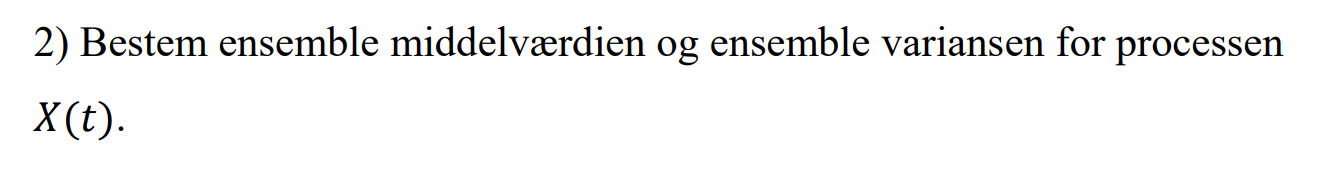

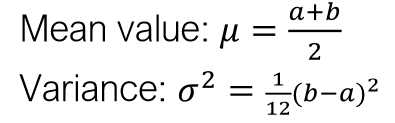

a= -2;
b = -1;
format rat
middel = (a+b)/2

middel =       -3/2     


variance2=1/12*(b-a)^2

variance2 =        1/12    


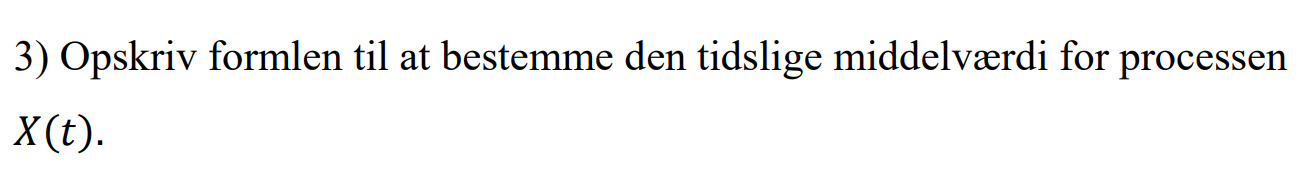

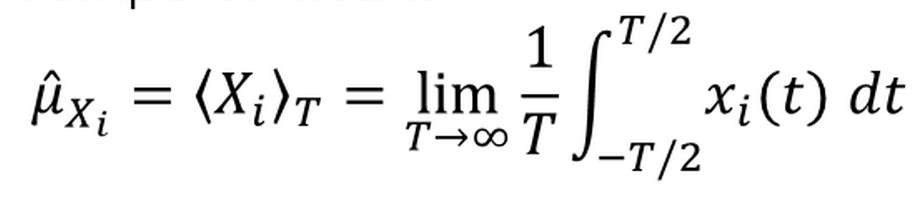

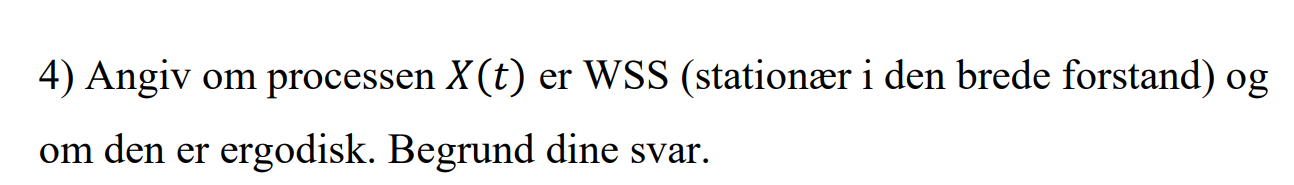

Processen er WSS da middelværdien og variansen ikke er tidsafhængig

Processen er ergodisk da tæthedsfunktionen kan findes ud fra en realistation når t -> uendelig

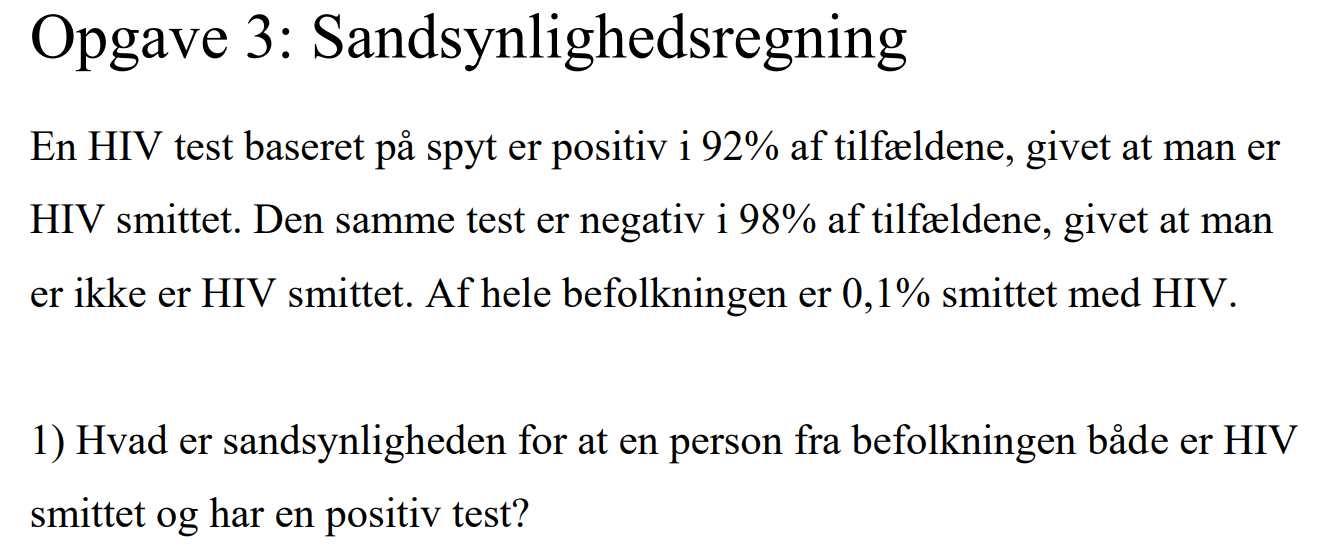

Hændelse A : Hiv smittet

Hændelse B = test positiv

format
Pr_H_T = 0.92;
Pr_NOT_H_NOT_T = 0.98;
Pr_H = 0.001;

Pr_hiv_test_positiv = Pr_H_T*Pr_H

Pr_hiv_test_positiv = 9.2000e-04

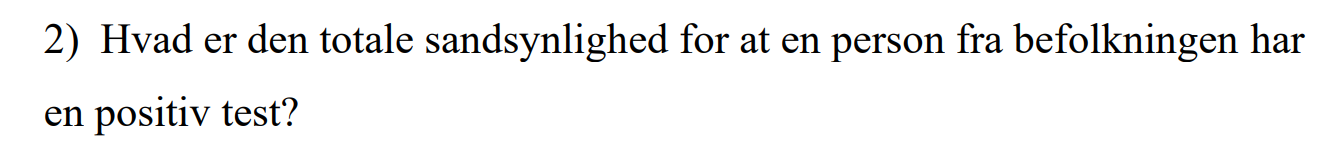

Positiv test = 92

Raske som får en positiv er 1-0.98 = 0.02

Pr_H_NOT_T=1-Pr_NOT_H_NOT_T;
Pr_NOT_H = 1-Pr_H;

Pr_T = Pr_NOT_H*Pr_H_NOT_T+Pr_hiv_test_positiv

Pr_T = 0.0209

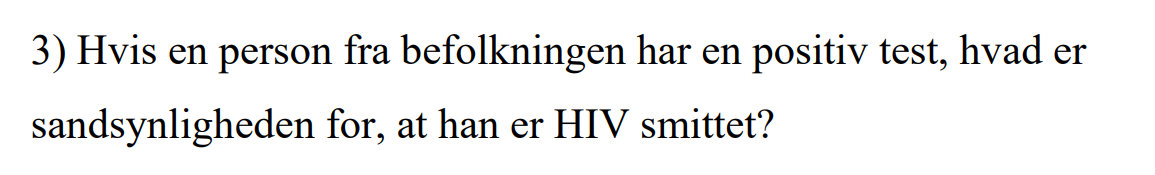

Pr_hiv_test_positiv/Pr_T

ans = 0.0440

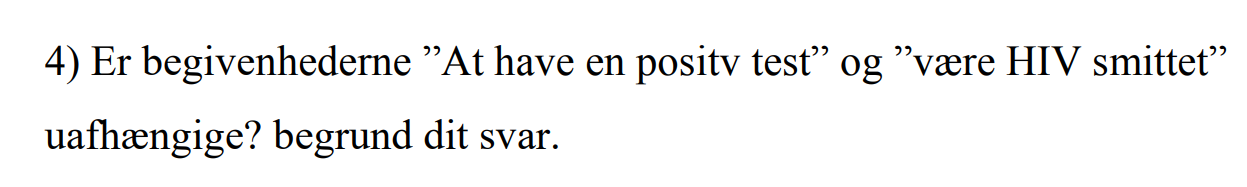

Pr_T*Pr_H

ans = 2.0900e-05


Pr_hiv_test_positiv

Pr_hiv_test_positiv = 9.2000e-04

Da overstående formel ikke er gældende, så kan vi bekræfte at de ikke er uafhængige. 

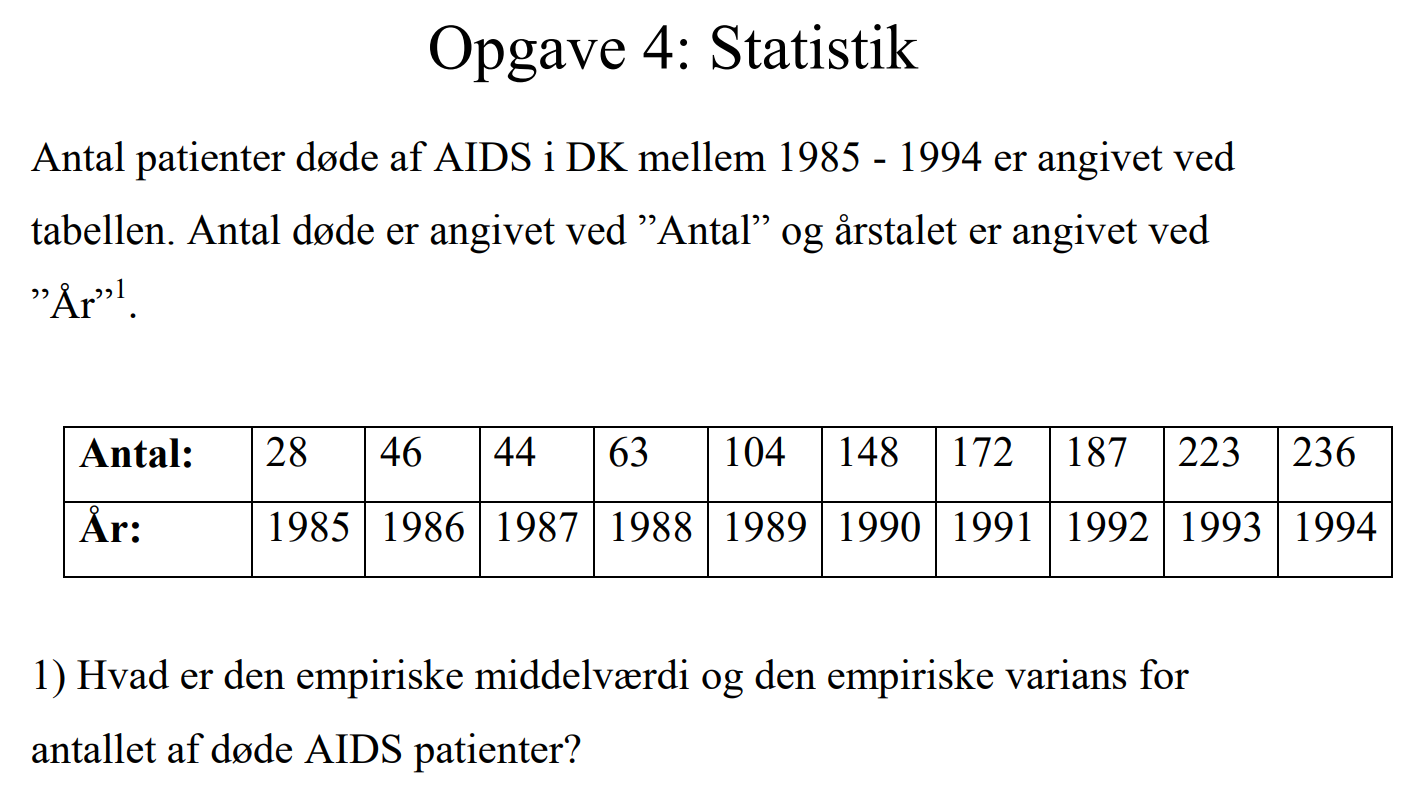

antal = [28 46 44 63 104 148 172 187 223 236];
years = 1985:1:1994;
emperiskeMiddel = mean(antal)

emperiskeMiddel = 125.1000

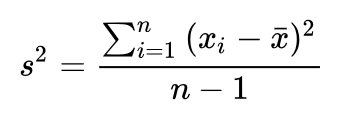

empiriskeVarianse2= sum((antal-emperiskeMiddel).^2)/(length(antal)-1)

empiriskeVarianse2 = 6.1114e+03

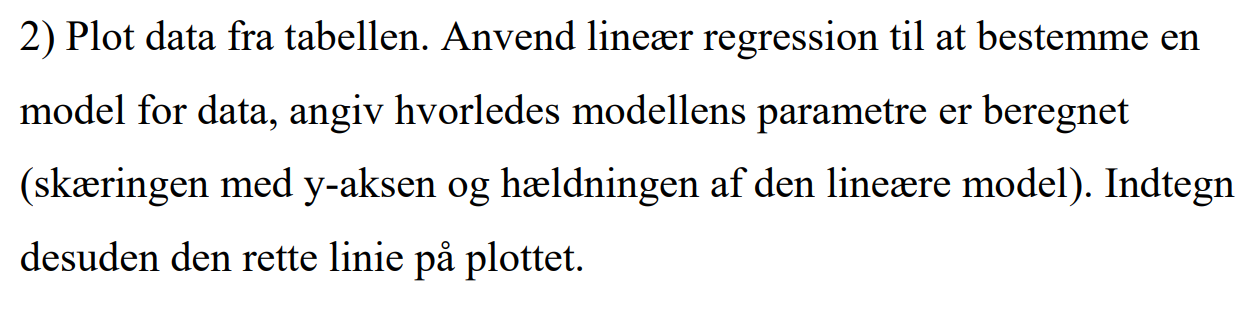

yearsMean = mean(years)

yearsMean = 1.9895e+03

Benytter følgende formel for at finde skæringen og hældningen

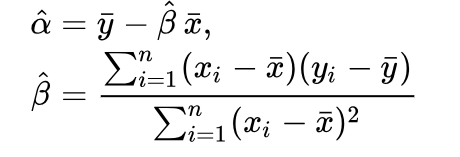

%Parameter estimat hældning
Beta = sum((antal - emperiskeMiddel) .* (years - yearsMean)) / sum((years - yearsMean).^2)

Beta = 25.4364


% Parameter estimat skæring
Alpha = emperiskeMiddel - Beta * yearsMean

Alpha = -5.0481e+04

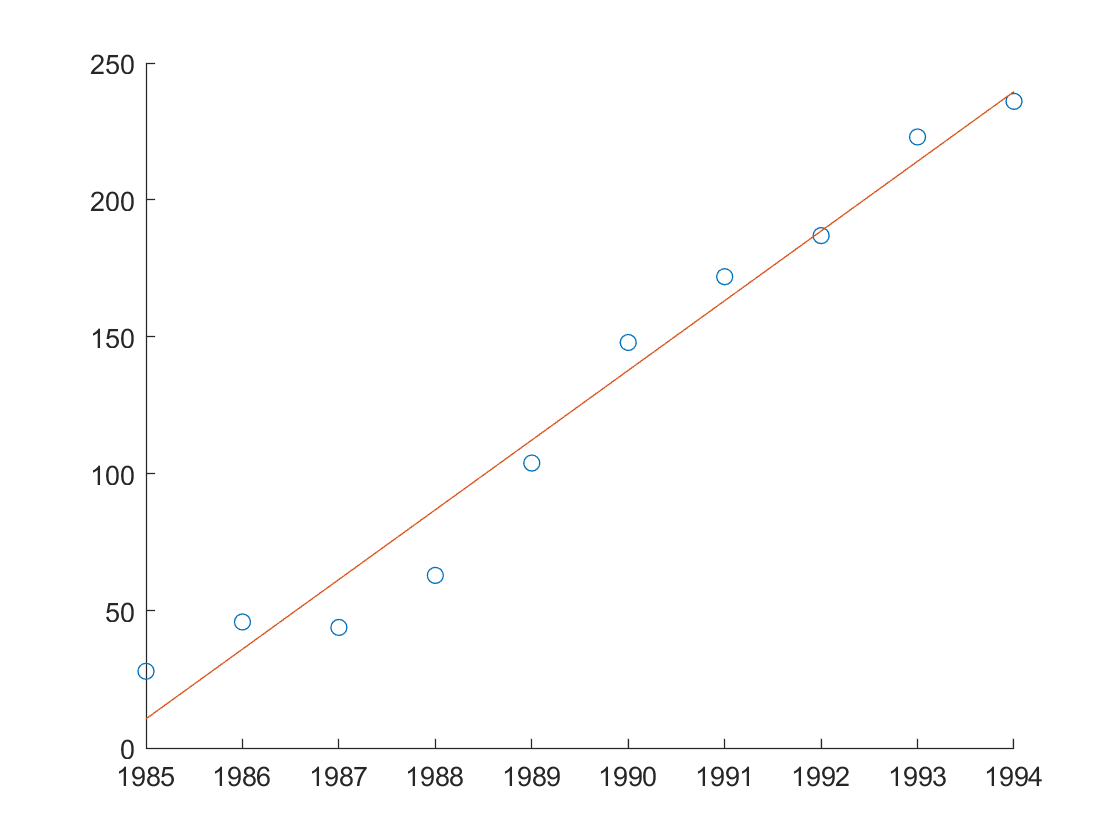

linearModel = Alpha + years * Beta;
figure(2)
hold on
scatter(years, antal)
plot(years,linearModel)

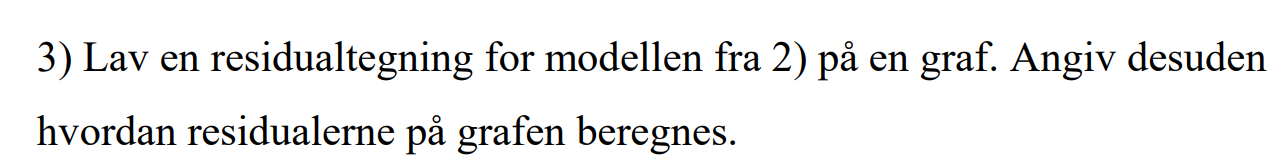

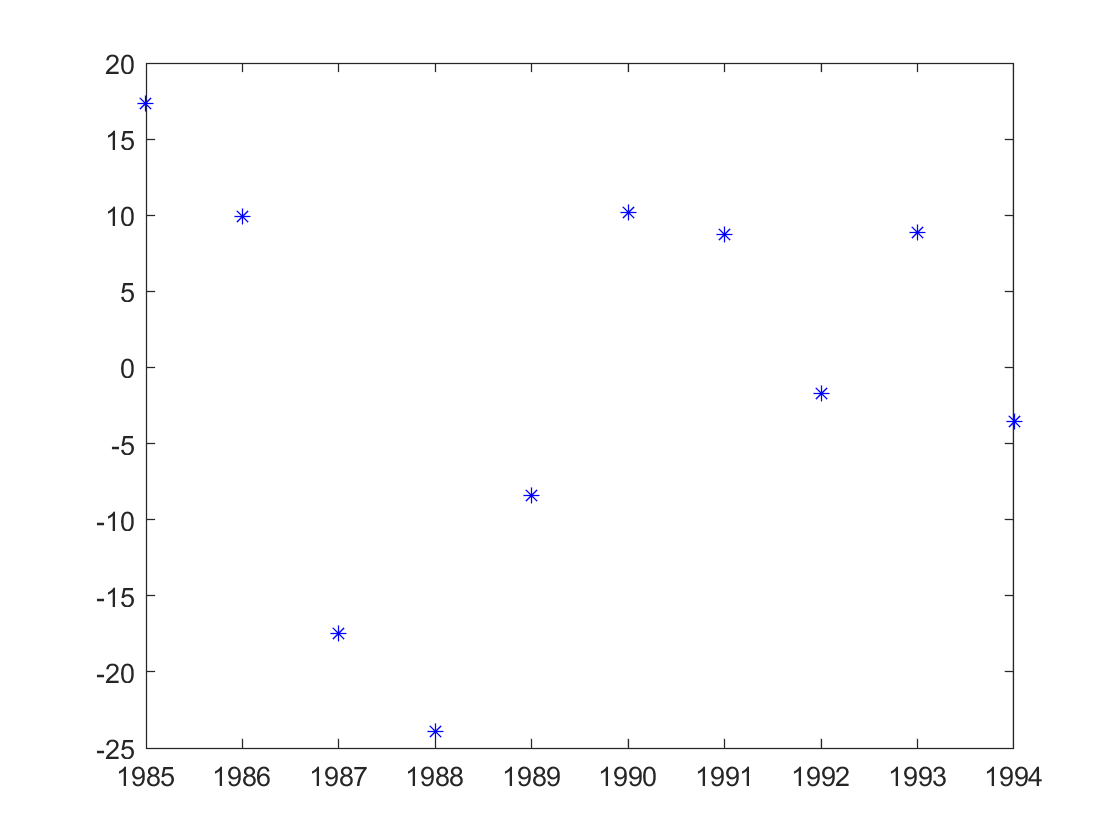

Residualtegning = antal - linearModel;
figure(3)
plot(years,Residualtegning,'b*')

Først findes standard deviationen 

n = length(antal)

n = 10

sr2 = 1/(n-2)*sum((Residualtegning).^2)

sr2 = 203.0864

t0 = tinv(0.975,(n-2))

t0 = 2.3060

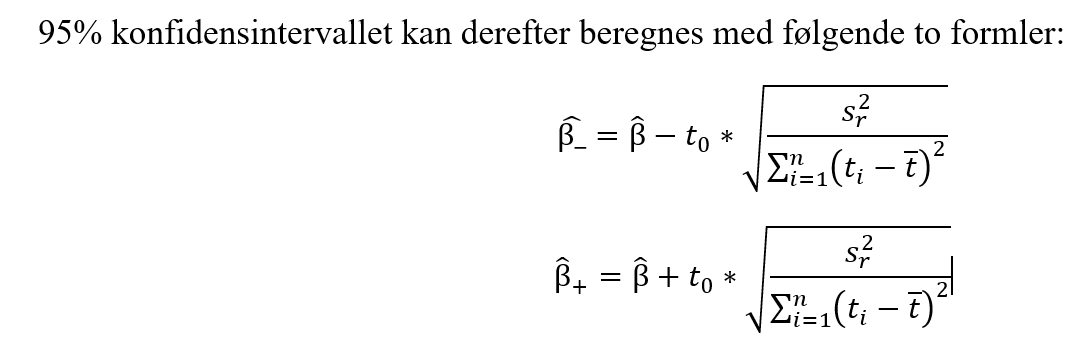

ConfMinus = Beta - t0 *sqrt(sr2/sum((years - yearsMean).^2))

ConfMinus = 21.8183

ConfPositiv = Beta + t0 *sqrt(sr2/sum((years - yearsMean).^2))

ConfPositiv = 29.0544

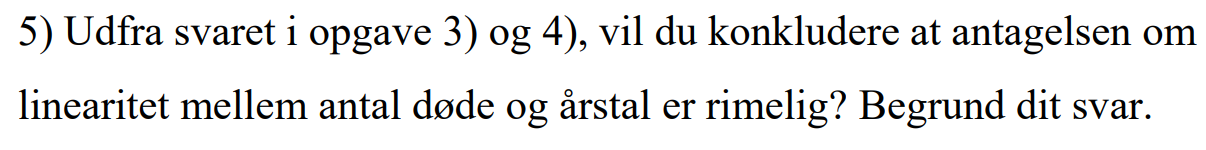

Udfra residualplottet er residualerne fordelt pænt omkring 0. Der er altså ikke et tydeligt mønster. Desuden ligger konfidensintervallet mellem 21.8183 og 29,0544 og altså tæt. Antagelsen om linearitet virker derfor rimelig. 

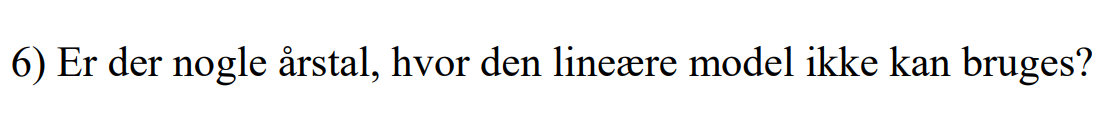

Årstal hvor antallet er negativt kan ikke bruges.